# Lab 8: Extended Kalman filter for navigation and tracking

Team1: Dmitry Shadrin, Eugenii Israelit, Sergey Golovanov @Skoltech

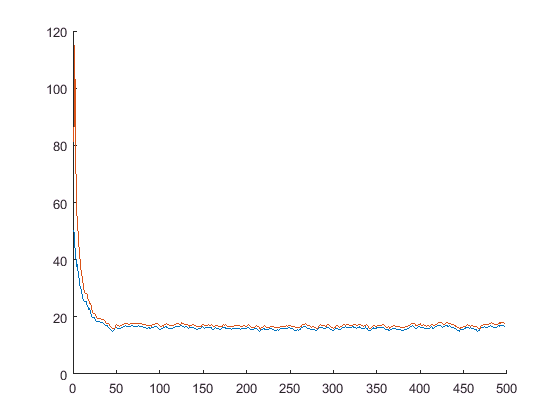

clc; clear; close all;
addpath('functions/');

n = 500;
sigmaA = 0.3;
sigmaB=0.004;
sigmaD=50;
x1 = 1000;
vx1 = 10;
y1=1000;
vy1=10;
t = 1;
ErrSumextrD=0;
ErrSumfiltrD=0;
ErrSumextrB=0;
ErrSumfiltrB=0;
P = [10^10 0 0 0;
     0 10^10 0 0;
     0 0 10^10 0;
     0 0 0 10^10];
G = [(t^2)/2 0;
      t 0;
      0 (t^2)/2;
      0 t];
F = [1 t 0 0; 0 1 0 0; 0 0 1 t; 0 0 0 1];

Q=G*G'*sigmaA^2;
R=[sigmaD^2 0; 0 sigmaB^2];


M=500;

for i=1:M

    AccX =  normrnd(0, sigmaA, 1, n );
    AccY =  normrnd(0, sigmaA, 1, n );
    
    X  = calcTrajectory11( AccX, x1,vx1,t);
    Y  = calcTrajectory11( AccY, y1,vy1,t);    
    
    Bnoise=normrnd(0, sigmaB, 1, n );
    Dnoise=normrnd(0, sigmaD, 1, n );
    
    D=sqrt(X.^2+Y.^2);
    B=atan(X./Y);
    
    Dm=D+Dnoise;
    Bm=B+Bnoise;
    
    Z=[Dm; Bm];
    Z0= [Dm(1)*sin(Bm(1));0; Dm(1)*cos(Bm(1));0];
    
    [Xk,Dmextr,Dmfiltr,Bmextr,Bmfiltr] = calcKalmanExtended(Z,Z0, F, P, Q, R );
    
    Dk=sqrt(Xk(1,:).^2+Xk(3,:).^2);
    Bk=atan(Xk(1,:)./Xk(3,:)); 
    
    ErrCurextrD = ( Dmextr - D).^2;    
    ErrCurfiltrD = (Dmfiltr - D).^2;
    ErrCurextrB = ( Bmextr - B).^2;
    ErrCurfiltrB = (Bmfiltr - B).^2;

    ErrSumextrD = ErrSumextrD +  ErrCurextrD;
    ErrSumfiltrD = ErrSumfiltrD +  ErrCurfiltrD;
    ErrSumextrB = ErrSumextrB +  ErrCurextrB;
    ErrSumfiltrB = ErrSumfiltrB +  ErrCurfiltrB;
end
   
FinalErrorextrD = (  ErrSumextrD(3:end)./(M-1) ).^0.5;
FinalErrorfiltrD = (  ErrSumfiltrD(3:end)./(M-1) ).^0.5;
FinalErrorextrB = (  ErrSumextrB(3:end)./(M-1) ).^0.5;
FinalErrorfiltrB = (  ErrSumfiltrB(3:end)./(M-1) ).^0.5;



figure; hold on;
plot(FinalErrorfiltrD);
plot(FinalErrorextrD);

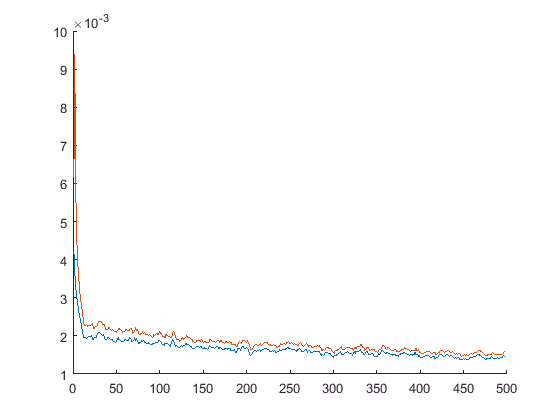

 title( sprintf ('Errors of exrapolation and filtration estimates of D \n sigmaA=0.3 sigmaD = 50  SigmaB =0.004 ') )
 legend('FinalErrorextrD', 'FinalErrorfiltrD'); 

figure; hold on;
plot(FinalErrorfiltrB);
plot(FinalErrorextrB);

 title( sprintf ('Errors of exrapolation and filtration estimates of B \n sigmaA=0.3 sigmaD = 50  SigmaB =0.004 ') )
 legend('FinalErrorextrB', 'FinalErrorfiltrB'); 


